# Non-linear Model Definition

## Load data from extrapolation

Data loading of the matrix of Force and Inductance.

load('parameters.mat')
disp(equilibrium(6:8,1:3));

    Cards     Mass     Current
    _____    ______    _______

      6      0.8734     1.109 
      7       0.875     1.179 
      8      0.8766     1.232 



% Position conversion from scope's unit to [m].
scope_positions = positions;
positions = positionConversion(positions);
positionsMean = 0;
positionsVariance = 2.2129e-10;
intensityMean = 0;
intensityVariance = 0.0013

intensityVariance = 0.0013

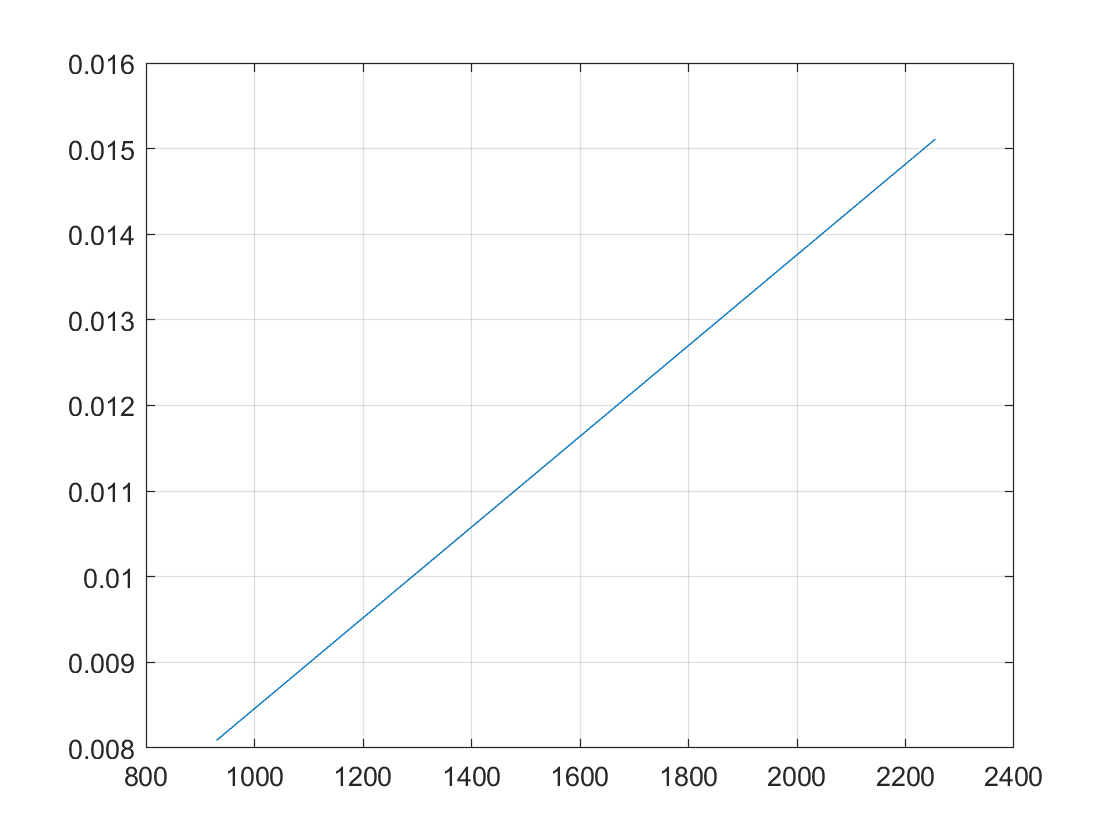

plot(scope_positions, positions)
grid on

## Linearization of Force around (x0, i0)

Around the equilibrium position chosen at 8 cards.

% Number of cards and relative position:
ncards=8;
[i0,x0,dfdi,dfdx,F0,dldi,dldx,L0] = equilibriumFeatures(F,LL,current,positions,equilibrium,ncards);
[ifin,xfin,~,~,~,~,~,~] = equilibriumFeatures(F,LL,current,positions,equilibrium,7);
initialConditions = [0;x0;i0]

initialConditions =          0
    0.0099
    1.2320


initialConditionsOBS = [0; 0.0008; 1]

initialConditionsOBS =          0
    0.0008
    1.0000


target = [0;xfin;ifin]

target =          0
    0.0105
    1.1790


% System matrix definition
[A, B, C, D] = magnetABCD(current, positions, F, LL, i0, x0)

A = 	1.0e+03 *

         0    1.7057    0.0158
    0.0010         0         0
         0         0   -0.0239


B =          0
         0
    5.8270


C =      0     1     0
     0     0     1


D =      0     0     0
     0     0     0


PolesUC = eig(A);

## Plot features after conversion.

Conversion from scope unit to [m], in addition I extracted the derivative of the force and inductance at the equilibrium position I am trying to stabilize the system at. In addition I computed the value of the matrices A,B,C,D at that specific position.

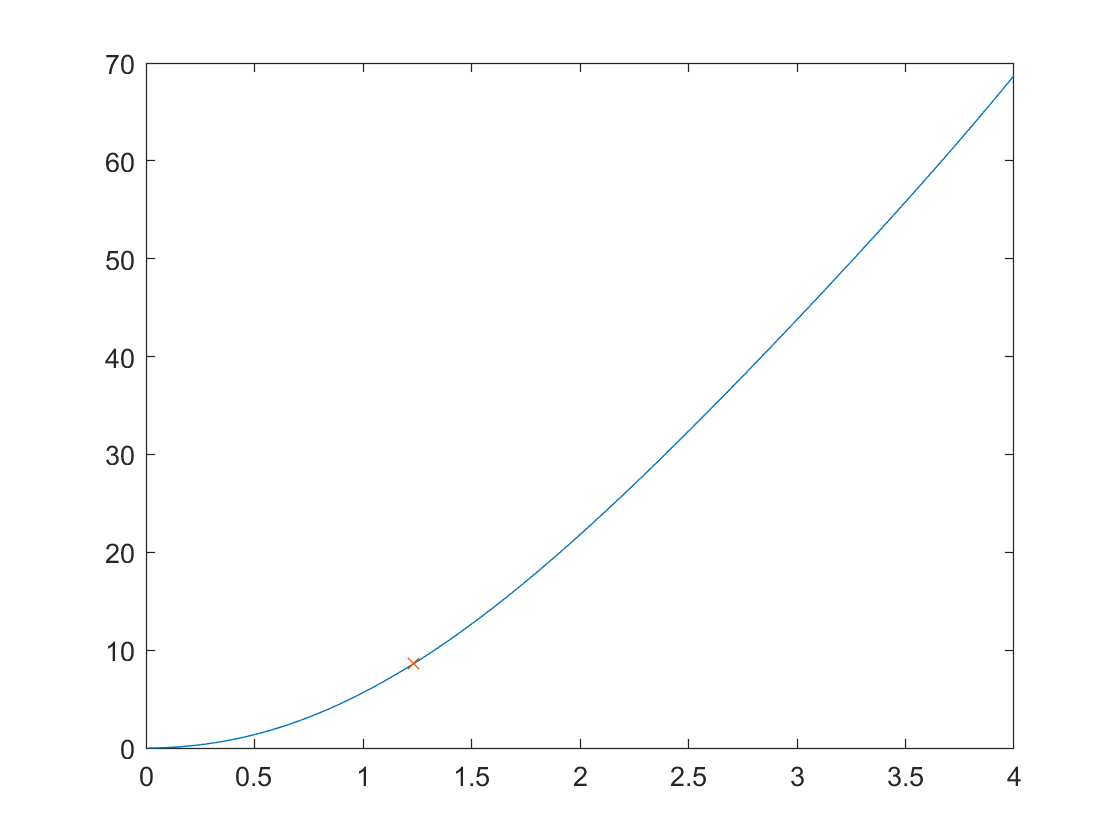

   13.8861



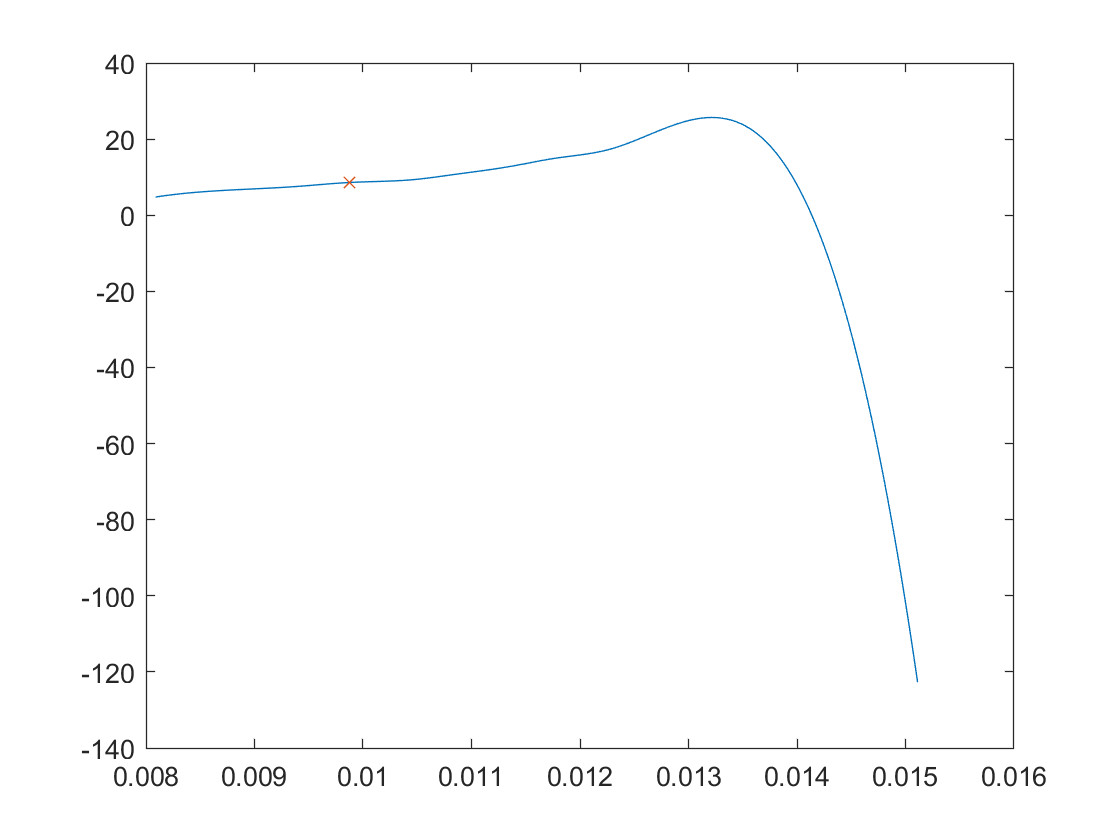

   1.4952e+03



plotFeatures(F,LL,current,positions,equilibrium,ncards)

## PID Controller

% Current Loop
Resistance = 4.1;
wcC = 1600;
PMC = 81.9335

PMC = 81.9335

kpc = 271;
kic = 6.81*1e4;


wcP = 2/0.00368316;
PMP = 100*0.85869;
kpp = 2.84*1e3;
kip = 3.79*1e4;
kdp = 53.3;

## LQR controller

Initialization and Normalization of the weigth matrices on States and Inputs.

Q = eye(3);
Q(1,1) = 1e5;
Q(2,2) = 1e7;
R = eye(1);
[Q, R] = normalizeQR(Q,R,0.01, 0.01, 4, 16);

% Gain matrix and Poles of the controlled system
[K,PP,PolesC] = lqr(A,B,Q,R);
coeff = B*K;
coeffLQR = coeff(3,:);

% Observer
PolesC

PolesC = 	1.0e+03 *

  -0.0100 + 0.0000i
  -4.8324 + 4.8322i
  -4.8324 - 4.8322i


PolesOBS = PolesC + 100*real(PolesC)

PolesOBS = 	1.0e+05 *

  -0.0101 + 0.0000i
  -4.8808 + 0.0483i
  -4.8808 - 0.0483i


Ktrans = place(A',C',PolesOBS);
KoLQR = Ktrans'

KoLQR = 	1.0e+11 *

    2.3824    0.0000
    0.0000         0
         0    0.0000


## Poles Plot LQR + Leumberger

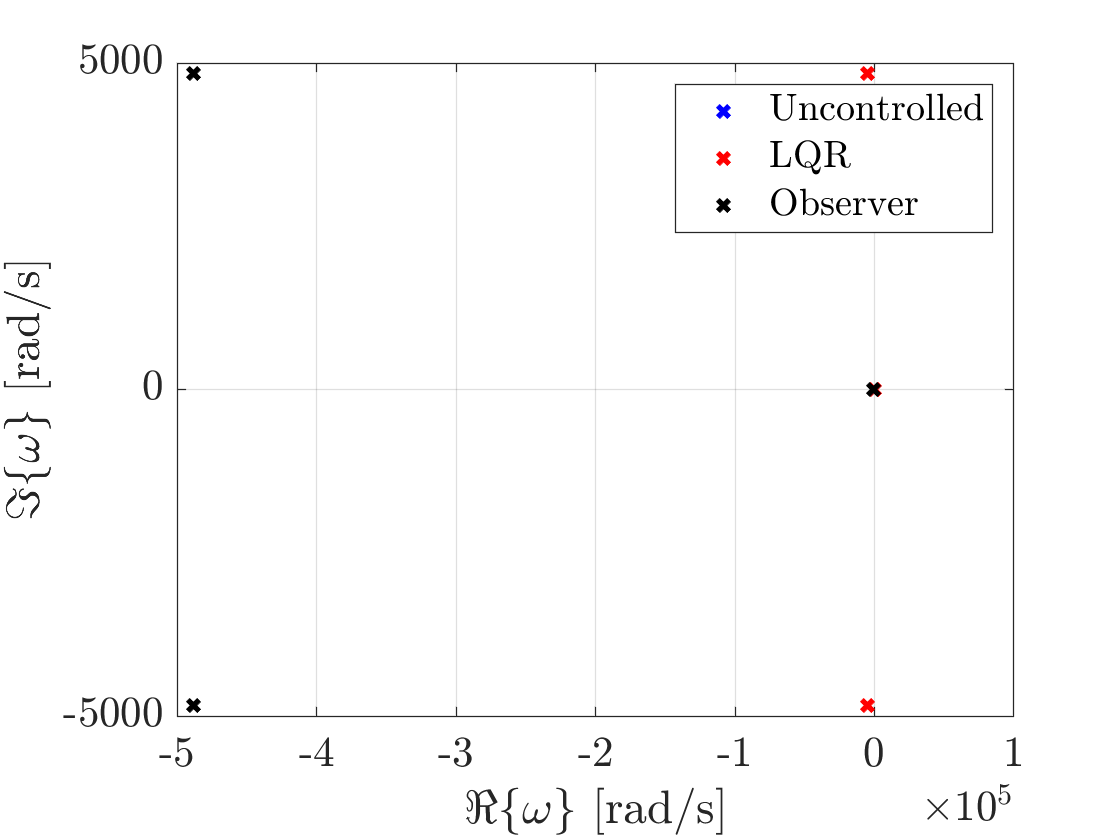

FigTag = figure;
ax = axes;
hold on; grid on; box on;
plot(real(PolesUC),imag(PolesUC),'x','LineWidth',2,'color','b');
plot(real(PolesC),imag(PolesC),'x','LineWidth',2,'color','r');
plot(real(PolesOBS),imag(PolesOBS),'x','LineWidth',2,'color','k');
xlabel('$\Re\{\omega\}$ [rad/s]','Interpreter','LaTex')
ylabel('$\Im\{\omega\}$ [rad/s]','Interpreter','LaTex')
legend({'Uncontrolled','LQR','Observer'},'Interpreter','LaTex')
ax.FontSize = 16;
ax.TickLabelInterpreter = 'LaTex';

## Pole Placement

% Target Poles of the system
PolesC = [-200 -150 -100]

PolesC =   -200  -150  -100


K = place(A,B,PolesC)

K = 	1.0e+04 *

    0.0723    4.0817    0.0073


coeff = B*K;
coeffPP = coeff(3,:)

coeffPP = 	1.0e+05 *

    0.0421    2.3784    0.0043


## Kalman Filter

% Q is the measurement about my system reliability:
Qk = zeros(3,3);
Qk(1,1) = 1;
Qk(2,2) = 1;
Qk(3,3) = 1;

% how much the measurements are reliable?
Rk = [0.00001,0;0,0.00001];
% Rk = [0.01,0;0, 0.01];
% Rk = [1,0;0,1];

%% OPTIMAL OBSERVER DESIGN

[~,~,Ko] = care(A',C',Qk,Rk);
KoK = Ko';

PolesOBS = eig(A'-C'*KoK');


## Poles Plot: Kalman + Pole Placement

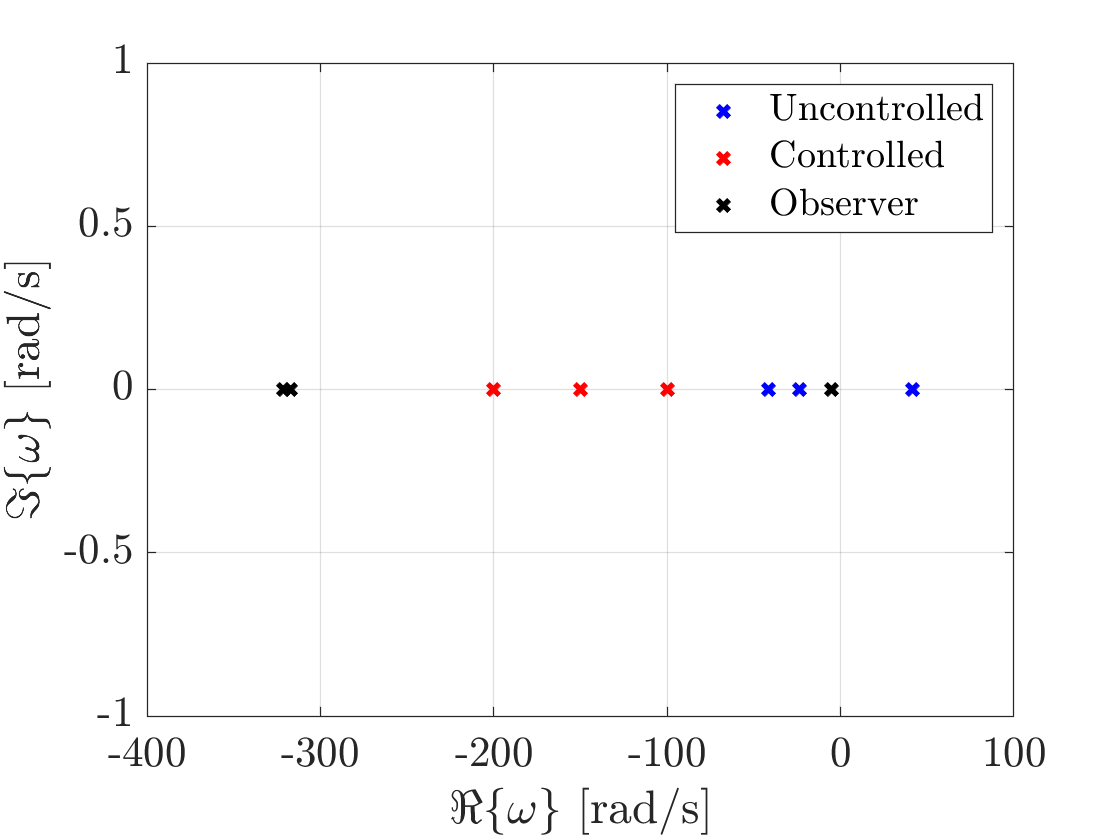

FigTag = figure;
ax = axes;
hold on; grid on; box on;
plot(real(PolesUC),imag(PolesUC),'x','LineWidth',2,'color','b');
plot(real(PolesC),imag(PolesC),'x','LineWidth',2,'color','r');
plot(real(PolesOBS),imag(PolesOBS),'x','LineWidth',2,'color','k');
xlabel('$\Re\{\omega\}$ [rad/s]','Interpreter','LaTex')
ylabel('$\Im\{\omega\}$ [rad/s]','Interpreter','LaTex')
legend({'Uncontrolled','Controlled','Observer'},'Interpreter','LaTex')
ax.FontSize = 16;
ax.TickLabelInterpreter = 'LaTex';